# Radio Communication System

## *Simulation Script*

Authors:

Leonard Berresheim - s0556126

Ali Jahanbakhsh       - s0565379

Mihail Milchev           - s0560818

clc, clear variables; % clear all variables
addpath('subfunctions'); % add directory "subfunctions" to path
format long;

*Note: When creating this script not enough effort has been put into making use of matlabs vectorisation. This causes the script to be very sluggish. We advise to comment the loop section in 5.2, as this seems to be taking especially long.*

## Global Simulation Parameters

**ebN0dB **defines the **S**ignal to **N**oise **R**atio *(short SNR)* per Bit in dB for the **A**dditive **W**hite **G**aussian **N**oise *(short AWGN)* that will be applied on the mapped signal later on. The system will be tested with varrious values for SNR

ebN0dB = 0:12; % SNR (per bit) in dB
nBits = 10e3; % simulate nBits bits per simulation loop

**Constellation **is the modulation format that will be use to map the incoming bitsequence.

As an example, for the modulation format **Q**uadrature **P**hase **S**hift **K**ey *(short QPSK) *the bitsequence is mapped according to *Table 1.*

% Table 1
Dezimalzahl = [0;1;2;3];
Bitwert = dec2bin(Dezimalzahl);
Index = [1;2;3;4];
Konstellationspunkt = [-1-i;-1+i;1-j;1+j];
table(Bitwert,Dezimalzahl,Index, Konstellationspunkt)

ans = 4×4 table
    Bitwert    Dezimalzahl    Index    Konstellationspunkt
    _______    ___________    _____    ___________________

      00            0           1             -1-1i       
      01            1           2             -1+1i       
      10            2           3              1-1i       
      11            3           4              1+1i       


*Notice:* *the index value is shifted by 1 due to the fact that matlab starts indexing at 1 instead of 0*

The modulation format is set using the function **DK16PCUe_ModFormats** that was provided by Professor Molle.

The return parameters of this function are as followed:

The vector **constellation **contains the constellation symbols.

The function handler **berTheoAWGN**(SNR, M) returns the theoretical **B**it-**E**rror-**R**elation of the **AWGN**-channel for chosen modulation format. It expects the **S**ignal-to-**N**oise-**R**atio in **linear** units and the number **M** of constellation symbols in given format.

The function handler **berTheoFading**(SNR, M, K) returns the theoretical **ber** of the **Rayleigh **and** Rician **fading channel. It additionaly also has as input parameter the **K**-factor.

 *(The**** AWGN/Rayleigh ****and**** Rician**** channel will be explained in more detailed later on)*

**M **gives the number of constalltion symbols in the format. 

[constellation, berTheoAWGN, berTheoFading, M] = DK16PCUe_ModFormats('qpsk');

## Simulation 

*Initially the simulation will be happening sequentially and vectorized, to have a better look at what the individual functions are doing. Later on (see 5.2) the simulation will be excecuted in a loop-*

### 3.1 Generating the bitsequence

**generateBits()** generates a *(uniformly distributed pseudo-)* random bitsequence of length **nBits**.

bits = generateBits(nBits);

### **3.2 Mapping the bitsequence**

**mapper() **maps the bitsequence **bits** according to the modulation format **constellation** defined before.

mapped_signal = mapper(bits, constellation);

### 5.1 Adding AWGN to the mapped signal

**add_awgn() **adds the noise to the mapped signal **mapped_signal **for each SNR value in **ebN0dB**.

mapped_signal_AWGN_noise = add_awgn(mapped_signal,ebN0dB,M);

### 4.1 Decision of received symbols

Due to the faultiness of the transmission channel, the signal at the output of the channel doesn't match the constellation points of the constellation format.

**decision() ** matches each constellation point of mapped_signal_AWGN_noise to the nearest constellation point in **constellation;**

decided_signal = decision(mapped_signal_AWGN_noise, constellation);

### 4.2 Demapping the signal

**demapper() **demappes the signal according to the constellation table.

As an example, for the modulation format **Q**uadrature **P**hase **S**hift **K**ey *(short QPSK) *the signal is demapped arcording to *Table 2.*

% Table 2
Dezimalzahl = [0;1;2;3];
Bitwert = dec2bin(Dezimalzahl);
Index = [1;2;3;4];
Konstellationspunkt = [-1-i;-1+i;1-j;1+j];
table(Konstellationspunkt,Index,Dezimalzahl, Bitwert)

ans = 4×4 table
    Konstellationspunkt    Index    Dezimalzahl    Bitwert
    ___________________    _____    ___________    _______

           -1-1i             1           0           00   
           -1+1i             2           1           01   
            1-1i             3           2           10   
            1+1i             4           3           11   


demapped_bits = demapper(decided_signal,constellation);

### Counting Errors

**nErr **is the number bits for which **demapped_bits** differs from the original bit sequence **bits**.

**ber ***(****b****it ****e****rror ****r****atio) *is the ratio between the number of error bits and the length of the bit sequence

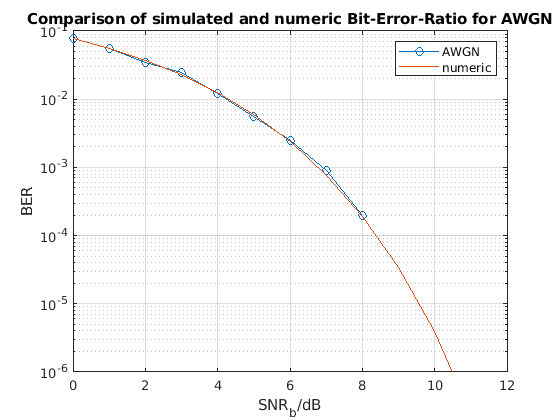

[nErr,ber] = countErrors(demapped_bits,bits);
% Numerische Berechnung
% P_AWGN = 0.5*erfc(sqrt(ebN0dB)); - This is not necessary anymore because
% we get this value and others from the function DK16PCUe_ModFormats

% ebN0dB needs to be converted from dB to linear units first
P_AWGN = berTheoAWGN(10.^(ebN0dB./10)*log2(M),M);


% Semi-logarithmic plot
semilogy(ebN0dB, ber, "-o", ebN0dB, P_AWGN);
title("Comparison of simulated and numeric Bit-Error-Ratio for AWGN")
xlabel("SNR_b/dB")
ylabel("BER")
grid on
legend('AWGN', 'numeric')

xlim([0 12])
ylim([10^(-6) 10^(-1)])

## 5.2 Simulation as a loop

*So far the simulation has been done with a fixed number of Bits. This doesnt necessarily give an informative Bit-Error-Ratio. *

*Hence the simulation will now be implemented as a loop with a specified number of Errors and a specified number of Bits before the simulation terminates*

### Defining simulation parameters

The simulation will terminate when **nMinErr **are reached or when **nMaxBits** are exceeded.

In the simulation loop **nBitsPerLoop** bits will be handled at once.

The simulation will return the **ber** *(Bit-Error-Ratio)* for each **SNR** *(Signal-to-Noise-Ratio)*

nMinErr = 100;
nBitsPerLoop = 10e3;
nMaxBits = 10*nBitsPerLoop;
ber = zeros(length(ebN0dB), 1);

### Simulation loop

% for i=1:length(ebN0dB)
%     nBits = nBitsPerLoop;
%     nTotalErr = 0;
%     while((nTotalErr <= nMinErr) || (nBits <= nMaxBits))
%         bits = generateBits(nBitsPerLoop);
%         mapped_signal = mapper(bits, constellation);
%         mapped_signal_AWGN_noise = add_awgn(mapped_signal,ebN0dB(i),M);
%         decided_signal = decision(mapped_signal_AWGN_noise, constellation);
%         demapped_bits = demapper(decided_signal,constellation);
%         [nErr,x_ber] = countErrors(demapped_bits,bits);
%         
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%      
%         nTotalErr = nTotalErr + nErr;
%         nBits = nBits + nBitsPerLoop;
%     end
%     ber(i) = nTotalErr / nBits;    
% end

% Semi-logarithmic plot
% semilogy(ebN0dB, P_AWGN, ebN0dB, ber, "-o");
% title("Comparison of simulated and numeric Bit-Error-Ratio for AWGN")
% xlabel("SNR_b/dB")
% ylabel("BER")
% grid on
% legend('AWGN', 'numeric')
% xlim([0 12])
% ylim([10^(-6) 10^(-1)])

### Implement Rayleigh-channel

**radioFadingChannel() **generates **nSamp **normaly distributed complex channel**_coefs**. Later on this function has been extended to also implement the rice channel coefficients, which also requires a **k**-factor. For the Rayleigh channel this factor is set to 0.

To implement the **Rayleigh** channel the **mapped_signal** is multiplied by the channel**_coefs**. Afterwards **A**dditive **W**hite **G**aussian **N**oise is added to the signal.

It is assumed that the receiver has estimated the channel idealy. 

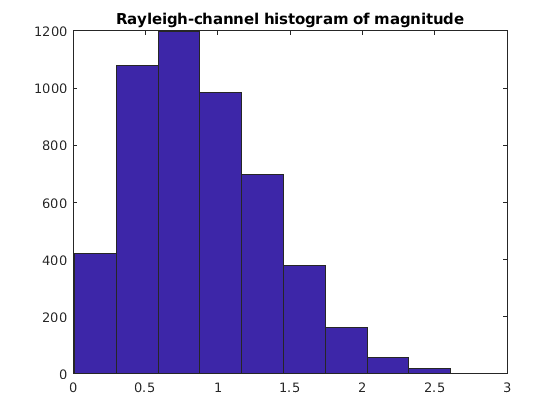

k = 0;
nSamp = length(mapped_signal);
channel_coefs = radioFadingChannel(nSamp,k);
hist(abs(channel_coefs)); % Vergleichen mit Vorlesung
title("Rayleigh-channel histogram of magnitude")

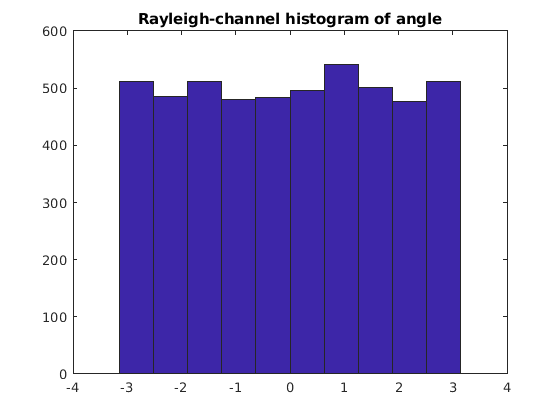

hist(angle(channel_coefs));
title("Rayleigh-channel histogram of angle")

To implement the **Rayleigh** channel the **mapped_signal** is multiplied by the channel**_coefs**. 

mapped_signal_fading = mapped_signal .* channel_coefs;

Afterwards **A**dditive **W**hite **G**aussian **N**oise is added to the signal.

mapped_signal_fading_AWGN = add_awgn(mapped_signal_fading,ebN0dB,M);

It is assumed that the receiver has estimated the channel idealy. Therefore the **signal **is compensated with the channel**_coefs**.

mapped_signal_received =  mapped_signal_fading_AWGN ./ channel_coefs;

Then we procede as usual:

The **mapped_signal_received** is decided according to the **constellation **symbols.

decided_signal = decision(mapped_signal_received, constellation);

The **decided_signal **is demapped.

demapped_bits = demapper(decided_signal,constellation);

The **demapped_bits **are compared to the initial **bits **and the **n**umber of **err**ors as well as the **b**it-**e**rror-**r**ation are computed. 

[nErr,ber] = countErrors(demapped_bits,bits);

The function handler **berTheoFading** returns the numeric **ber** value for the **Rayleigh** channel with a **k** value of 0.

P_Rayleigh = berTheoFading(10.^(ebN0dB./10)*log2(M),M,0);

The function handler **berTheoAWGN** returnx the numeric **ber** value for the **AWGN** channel

*Note: The function handlers expect the SNR per symbol in linear, hence the conversion from SNR per bits in dB*

P_AWGN = berTheoAWGN(10.^(ebN0dB./10)*log2(M),M);

The numeric and simulated values are compared in a semi-logarithmic plot.

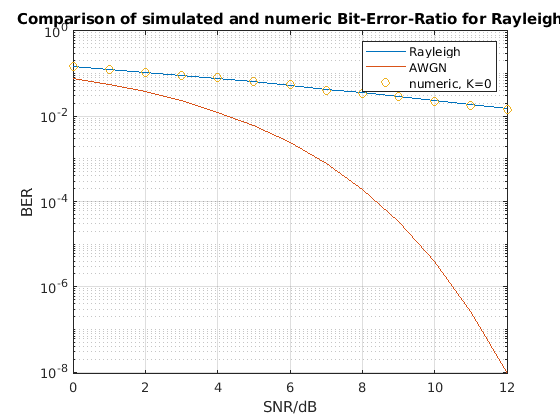

semilogy(ebN0dB, P_Rayleigh, ebN0dB, P_AWGN, ebN0dB, ber, "o");
title("Comparison of simulated and numeric Bit-Error-Ratio for Rayleigh")
xlabel("SNR/dB")
ylabel("BER")
grid on
legend('Rayleigh', 'AWGN', 'numeric, K=0')

### Implement Rice-channel

For **k **values greater **0**, **radioFadingChannel() **computes **nSamp** **channel_coefs** for the **Rice** channel.

*Simulating the Rice channel works analoguously to the Rayleigh channel simulation*

The **Rice** channel is simulated for several **k**-factor values.

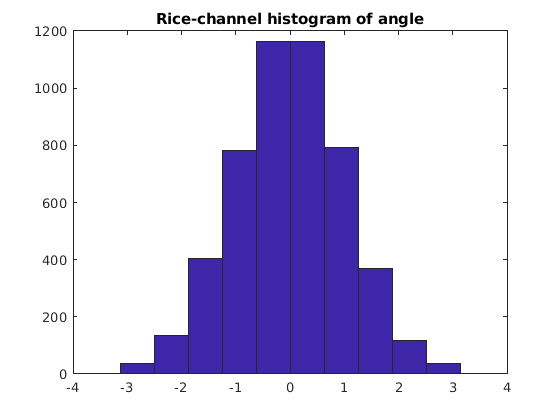

k = [0,1,2,5,10];
ber = zeros(length(ebN0dB), length(k));
P_Rice = zeros(length(ebN0dB), length(k));
for i = 1:length(k)
    nSamp = length(mapped_signal);
    channel_coefs = radioFadingChannel(nSamp,k(i));
    hist(abs(channel_coefs));
    title("Rice-channel histogram of magnitude")
    hist(angle(channel_coefs));
    title("Rice-channel histogram of angle")
    
    mapped_signal_fading = mapped_signal .* channel_coefs;
    
    mapped_signal_fading_AWGN = add_awgn(mapped_signal_fading,ebN0dB,M);
    
    mapped_signal_received =  mapped_signal_fading_AWGN ./ channel_coefs;
    
    decided_signal = decision(mapped_signal_received, constellation);
    
    demapped_bits = demapper(decided_signal,constellation);
    
    [nErr,ber(:,i)] = countErrors(demapped_bits,bits);
    P_Rice(:, i) = berTheoFading(10.^(ebN0dB./10)*log2(M),M,k(i));
end

P_AWGN = berTheoAWGN(10.^(ebN0dB./10)*log2(M),M);

The numeric and simulated values are compared in a semi-logarithmic plot.

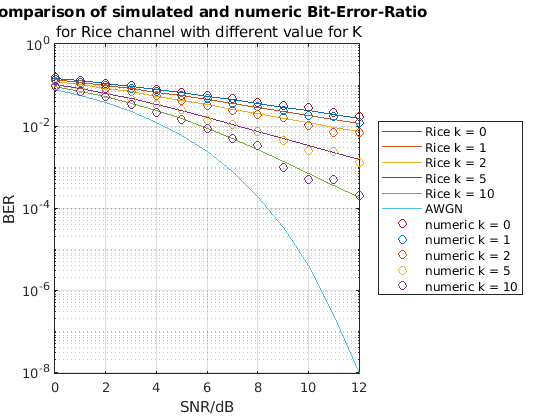

semilogy(ebN0dB, P_Rice, ebN0dB, P_AWGN, ebN0dB, ber, "o");
title("Comparison of simulated and numeric Bit-Error-Ratio"," for Rice channel with different value for K")
xlabel("SNR/dB")
ylabel("BER")
grid on
lgd = legend('Rice k = 0', 'Rice k = 1', 'Rice k = 2', 'Rice k = 5', 'Rice k = 10', 'AWGN', 'numeric k = 0', 'numeric k = 1', 'numeric k = 2', 'numeric k = 5', 'numeric k = 10');
lgd.Location = 'eastoutside';